syms x;
y = x^4  - 2*x^3  + x/2 + 1

$$y = x^{4}-2\,x^{3}+\frac{x}{2}+1$$

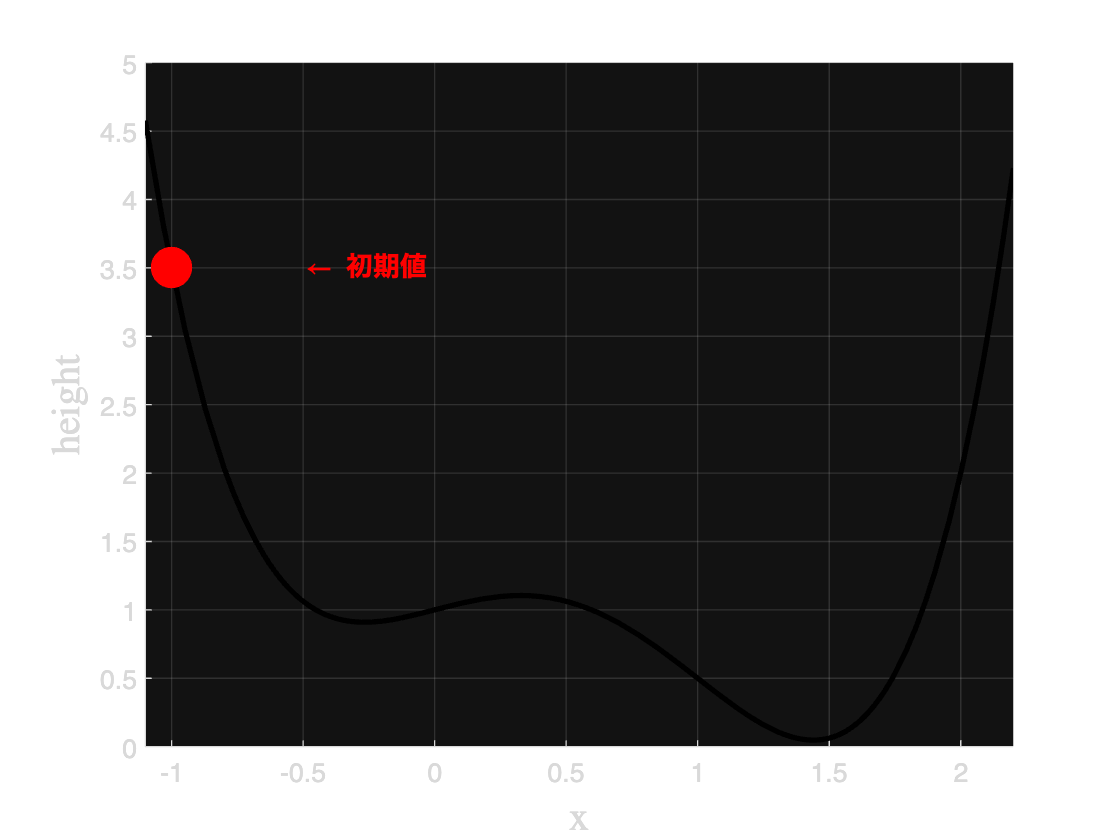

xs = -1;

figure;
hold on
grid on
fplot(y, 'LineWidth',2, 'Color','k');
plot(xs,subs(y,x,xs),'ro','MarkerFaceColor','r','MarkerSize',15);
ax_text = text(xs+(diff(get(gca,'XLim')))/20,subs(y,x,xs),'\leftarrow 初期値','FontSize',10,'FontWeight','bold','Color','r');
xlabel('x','fontsize',15,'Interpreter','latex')
ylabel('height','fontsize',15,'Interpreter','latex')

tf =  true;
if tf
    x0 = -1.1;
    x1 = 2.2;
    if x0>=x1
        error('x軸の範囲が存在しません')
    end
    xlim([x0,x1])
end

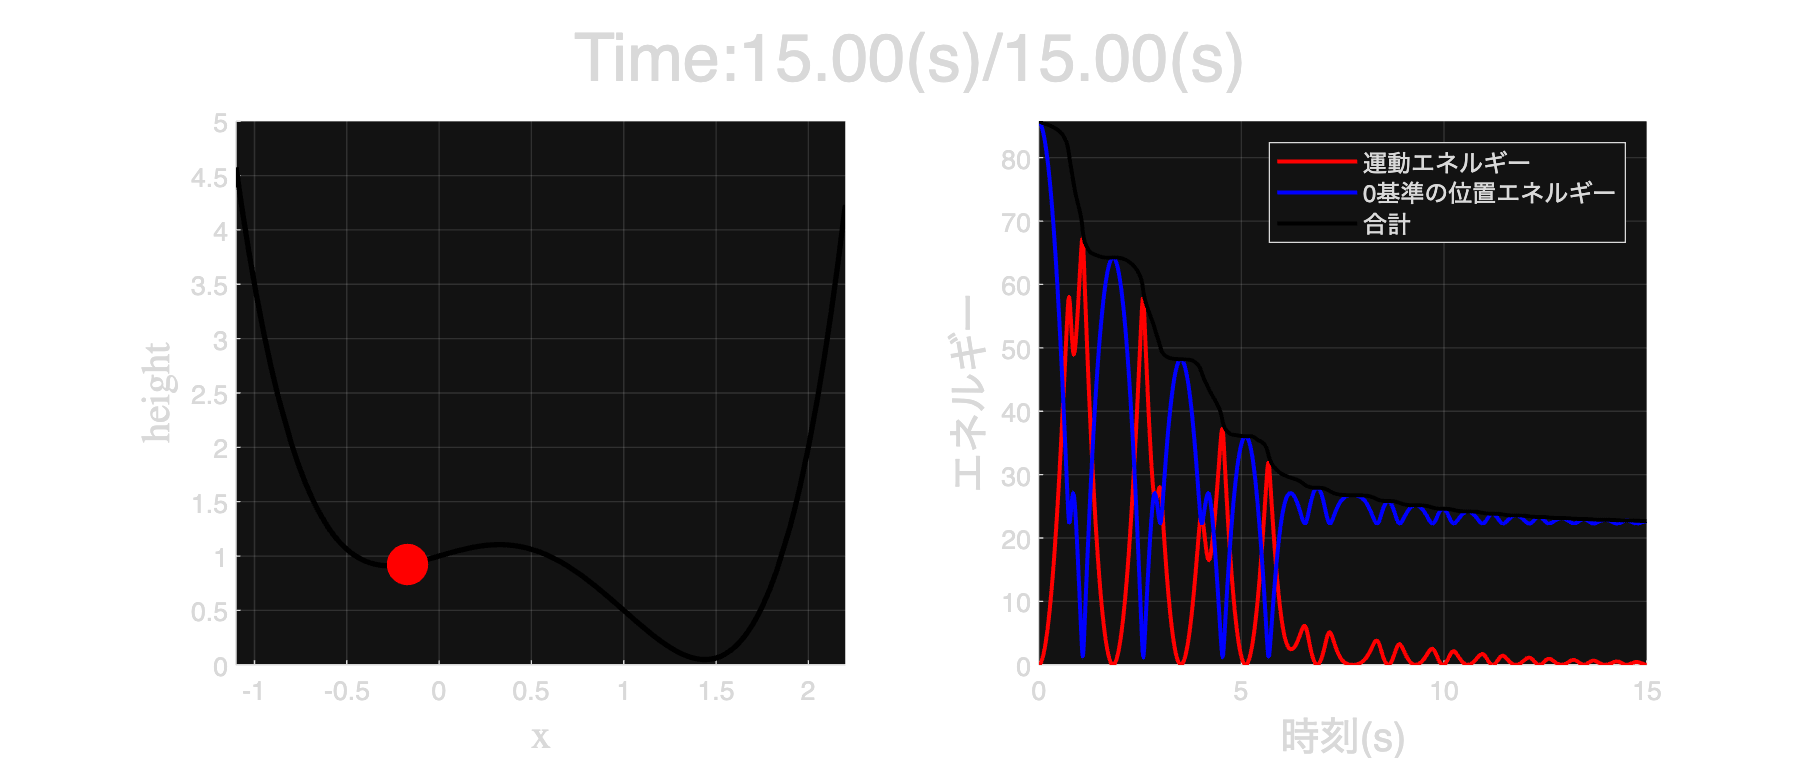

 
m  = 2.5;
g  = 9.8;
nu = 1;
tend = 15;

fy  = matlabFunction(     y ,'vars', {'x'});
dy  = matlabFunction(diff(y),'vars', {'x'});
dx  = @(t,x) [  x(2)/sqrt(1+dy(x(1))^2); ...
                (- m*g*sin(atan(dy(x(1)))) - nu*cos(atan(dy(x(1))))*(x(2)) )/m];
sol = ode15s(dx,[0,tend],[xs;0]);

tspan= 1/60;
tsol = 0:tspan:tend;
xsol = spline(sol.x,sol.y(1,:),tsol);
vsol = spline(sol.x,sol.y(2,:),tsol);
ysol = fy(xsol);

kinetic   = 1/2 * m * vsol.^2;
potential = m*g*ysol;
total     = kinetic + potential;



figure('Position',[0,0,1200,500]);

ax1 = subplot(1,2,1);
    hold(  ax1,'on'); 
    grid(  ax1,'on');
    fplot( ax1, y, 'LineWidth',2, 'Color','k');
    xlabel(ax1,     'x','fontsize',15,'Interpreter','latex')
    ylabel(ax1,'height','fontsize',15,'Interpreter','latex')
    ball    = plot(ax1, xs,subs(y,x,xs),'ro','MarkerFaceColor','r','MarkerSize',15);
    strTime = @(t) ['Time:',num2str(t,'%.2f'),'(s)/',num2str(tend,'%.2f'),'(s)'];
    timer   = sgtitle(strTime(0),'FontSize',25);
    if tf; xlim(ax1,[x0,x1]); end

ax2 = subplot(1,2,2);
    hold(ax2,'on')
    grid(ax2,'on')
    set( ax2,"XLim",[0,tend],"YLim",minmax([kinetic,potential,total]))
    l = cellfun(@(c) animatedline(ax2,'Color',c,'LineWidth',1.5), {'r','b','k'});
    legend(ax2,l,{'運動エネルギー','0基準の位置エネルギー','合計'})
    xlabel(ax2,'時刻(s)','fontsize',15)
    ylabel(ax2,'エネルギー','fontsize',15)

for idx = 1:numel(tsol)
    ball.XData = xsol(idx);
    ball.YData = ysol(idx);
    timer.String = strTime(tsol(idx));
    addpoints(l(1),tsol(idx),  kinetic(idx));
    addpoints(l(2),tsol(idx),potential(idx));
    addpoints(l(3),tsol(idx),    total(idx));
    drawnow limitrate
    pause(0.01)
end